## Generating Images and Postprocessing

This is a livescript, similar to a jupyter notebook in python. 

Use these controls. Primarly the "Run and Advance" button. 

This document will serve as a reference for running data, in this case the Burgers data. The data was pre-

generated and stored in a mat file. However the data can be generated using the same process.

-Add our paths to our dependency

addpath('plotting_camera');     % Additional codes incase of missing packages. 
addpath('ptvcodes');            % Post Processing codes
addpath('extracodes\')          % Extra codes and helper functions
addpath(genpath('dependency')); % Folder containing a core PTV folder dependency. 

**Generate a new working folder **

% Name of our new working folder 
folder_name = 'Burgers_test_new';        % INPUT % 

% No Inputs % 
% Put all new test cases into a folder called "Test Cases" 
folder_path = ['test cases\',folder_name]

folder_path = 'test cases\Burgers_test_new'

if exist(folder_path)
    disp('Folder exist')
else
    % make that folder 
    mkdir(folder_path);
    % copy default contents into our new working folder 
    copyfile('dependency\Base_test_folder\',folder_path);
end
% Add new folder path 
addpath(genpath(folder_path));

**Specify our working folder**

% Working folder
work_dir = folder_path;

## Setting up our synthetic Camera configuration:

**1.default_camera**

Setting up the default camera parameters can be done by opening the defaultcamera.m and adjusting the values within the function.

open('defaultCamera.m')

**2. Setting up default camera Arrangement.**

The default camera arrangement is set in the defaultCameraArrangement.m file. 

Setting up the default camera Arrangement can be done by opening the defaultCameraArrangement.m and adjusting the values within the function. The function uses x_p y_p z_p inputs, i.e offsets and deals them out accordingly for each respective camera. 

open('defaultCameraArrangement.m');

We can plot the current camera configuration useing

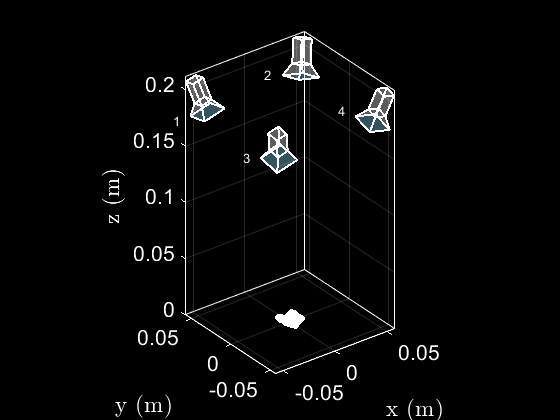

X-Range:-0.0064      0.0064; Y-Range:-0.0064      0.0064; Z-Range:0      0.0032


plotCameraArrangement()

or we can generate the structure, then update the values.

CAMERAS = defaultCameraArrangement();
% well make the structure into a table so it easily seen
T = struct2table(CAMERAS);
T(:,1:6)
T(:,7:end)

Essentially if we would like to update the camera position for a camera,

we would update the eye of said camera

% Updating camera eye (location of camera)
% For Camera 1 
CAMERAS(1) = setfield(CAMERAS(1),'Eye',[-.05,.05,.2]);
% For Camera 2 
CAMERAS(2) = setfield(CAMERAS(2),'Eye',[.05,.05,.2]);
% For Camera 3 
CAMERAS(3) = setfield(CAMERAS(3),'Eye',[-.05,-.05,.2]);
% For Camera 4 
CAMERAS(4) = setfield(CAMERAS(4),'Eye',[.05,-.05,.2]);
disp('% ---------  Updated Position Tables ---------  %')
% T(:,1:6)
T(:,9)

We can do this for any of the feilds for any of the cameras. 

**Note: Depending on the method you may need to pass in the update objected to **

**future functions. **

## Calibration Images

To generate calibration images we first need to specify the calibration directory:

% Working calibration folder 
cal_dir = [work_dir,'/cal'];

Calibration Images are generated by generating the target points and by rendering the images. 

The target points are generated using  **calibrationTarget.m**

The points are adjusted by adjusting the dot spacing value. When the function is ran, the bounds of the points are 

returned. 

addParameter(p, 'dotSpacing', 0.0032, @isnumeric); %  0.0254,0.032 % XY directions

addParameter(p, 'dotSpacing_z', 0.0016, @isnumeric); %  0.0254,0.032 % Z direction

open('calibrationTarget.m')

[x,y,z, xc, yc, zc] = calibrationTarget();

X-Range:-0.0064      0.0064; Y-Range:-0.0064      0.0064; Z-Range:0      0.0032


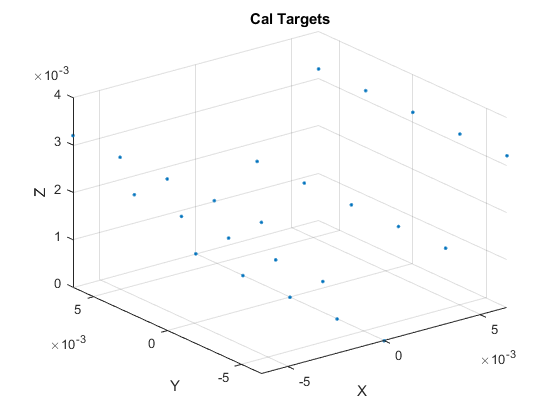

figure
plot3(xc,yc,zc,'.')
xlabel('X');ylabel('Y');zlabel('Z');grid on
title('Cal Targets')

clf;

**Using the CalTargetMultiView function, synthetic calibration images can be generated by passing in a few functions. **

**Open the calTargetMultiViw to see the input parameters:**

**The main Parameters:**

addParameter(p, 'plot', true, @islogical); % SHOW IMAGES 

addParameter(p, 'cameras', defaultCameraArrangement(), @isstruct); % Load the cameras 

addParameter(p, 'cal_dir', 'test/cal', @isstr); % Directory to Save files

addParameter(p, 'save', false, @islogical); % Save files 

addParameter(p, 'TargetFile', true, @islogical); % Save Target file for PTV

addParameter(p, 'target_3D', true, @islogical); %  3D Calibration Target. 

addParameter(p, 'plot_camera', false, @islogical); %SHOW CAMERA PLACMENT. 

addParameter(p, 'generate_ori', false, @islogical); % Generate ORI FILES FOR PTV

Then we can generate the calibration images using: 

calTargetMultiView('save',true,'cal_dir',cal_dir,'TargetFile', true,'target_3D',...
true,'generate_ori', true,'plot_camera',true);
% or pass in the camera structure

% calTargetMultiView('cameras',CAMERAS,'save',true,'cal_dir',cal_dir,'TargetFile', true,'target_3D',...
% true,'generate_ori', true,'plot_camera',true);

## Flow Images:

    To generate images of the particle postions, we need to specify the image directory and ensure that the folder is empty. This code will specify said directory, and if it exist already, it will remove it.

img_dir  = [work_dir,'/img'];
if exist(img_dir)
% Remove the exiting img folder
    disp('exist')
    rmdir(img_dir,'s')
    disp('Removed image directory')
end

exist


Removed image directory


### Data Structure for Image generation

We need to pass data into the makeImageUniversal function. 

The data must be in a structure with fields,x,y,z. Where x,y,z are matrices containing the particle locations in time. 

Example: if is in the form X = [ 70x100 ] then 70 is the number of time steps and 100 is the number of particles and or trajectories.

Therefore, X(1,:) contains all the X locations of all the particles at time t=1. 

Once we have the matrices X,Y,Z, they must be packed intro a data structure. The data structure follows the form:

test_data.x = X;

test_data.y = Y;

test_data.z = Z ;

**For the Burgers Vortex Data we have 2 options. **

- **Utilize a pre generated data set ( This is ideal if you plan to study the same data )**

- **Generate a new data set ( This is ideal if you plan to modify how the data was generated. i.e seeding density. **

Well do both here for example purposes. 

### Option 1: load a pre generated data set. 

**This is the same process as the JHU data.** 

% Load the Pos.mat file. This file contains pre generated burgers data
load('Pos.mat')
% Some properties about this data set.
[time_steps,Number_trajectories] = size(Pos.x)
% Lets rename it 
test_data = Pos;

% Lets plot it
% plot for visual understanding
figure
plot3(Pos.x,Pos.y,Pos.z,'.')
title('Test data'); xlabel('X');ylabel('Y');zlabel('Z');grid on
clf;

This data is already scaled and ready for image generation. 

**Now we can generate the images using makeImage_universal. **

However, Like many of the other functions we can pass in parameters.

addParameter(p, 'cameras', defaultCameraArrangement(), @isstruct);

addParameter(p, 'outdir', '.', @isstr); % Where to Save 

addParameter(p, 'particleDiameterMean', 2*sqrt(8), @isnumeric); % 1.5 particleDiameterMean

addParameter(p, 'particleDiameterStdDev', 0.10 * sqrt(8), @isnumeric); %  particleDiameterStdDev

addParameter(p, 'beamStdDev', 0.05, @isnumeric); % Beam Standard dev

addParameter(p, 'BeamPlaneZ', 0, @isnumeric); % Bean plane

addParameter(p, 'save', false, @islogical); % Save Images

addParameter(p, 'plot', true, @islogical); % Plot the image sequence as it is rendered?

addParameter(p, 'data', [], @isstruct); % Our input data

**The default values can be modified by passing in the parameter. **

Here we will save the image the image sequence to our out directory, we wont plot the data, and well pass in the

data using 'data' and the test_data structure we made eariler. 

makeImages_universal('outdir',img_dir,'save',true,'plot',false,'data',test_data);

% or pass in the camera 
%makeImages_universal('cameras',CAMERAS','outdir',img_dir,'save',true,'plot',false,'data',test_data);

% Remove the tif 
remove_tif_M(img_dir);

### Option 2: Generate new data

Here we will utilize a new function, which generates the new data set and renders the images. This was the original way of generating the data. 

Remove existing img directory files. 

img_dir  = [work_dir,'/img'];
if exist(img_dir)
% Remove the exiting img folder
    disp('exist')
    rmdir(img_dir,'s')
    disp('Removed image directory')
end

makeImages('outdir',img_dir,'save',true,'plot',true,'xrange', [-.009, .009], 'yrange', [-.009, .009],...
    'zrange', [0, 0.003],'particleConcentration', 5.5e8,'save_positions', true,'tspan', linspace(0,0.01, 30));

    "test volume = "    "9.72e-07"    "m^3"

number of particles = 535
Generating new data


filename = 'test cases\Burgers_test_new\Particle_pos_.mat'

filename = 'test cases\Burgers_test_new\Particle_pos_1.mat'

Saving generated dataset


On frame 1 of 30


On frame 2 of 30


On frame 3 of 30


On frame 4 of 30


On frame 5 of 30


On frame 6 of 30


On frame 7 of 30


On frame 8 of 30


On frame 9 of 30


On frame 10 of 30


On frame 11 of 30


On frame 12 of 30


On frame 13 of 30


On frame 14 of 30


On frame 15 of 30


On frame 16 of 30


On frame 17 of 30


On frame 18 of 30


On frame 19 of 30


On frame 20 of 30


On frame 21 of 30


On frame 22 of 30


On frame 23 of 30


On frame 24 of 30


On frame 25 of 30


On frame 26 of 30


On frame 27 of 30


On frame 28 of 30


On frame 29 of 30


On frame 30 of 30


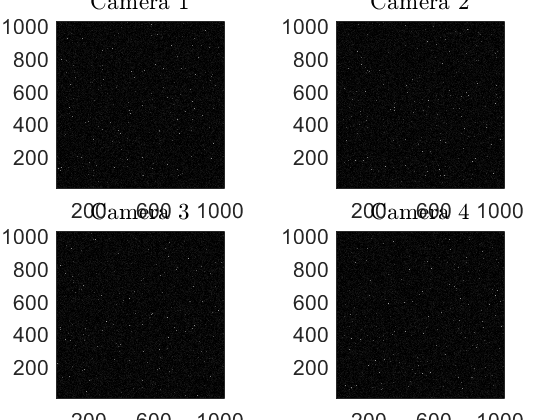

% Remove the tif 
remove_tif_M(img_dir);

**Go to the PTV folder we created and perform the following steps:**

1. Calibration

2. Tracking

Using default liboptv tracker

step: 10001, curr: 526, next: 523, links: 511, lost: 15, add: 410

step: 10002, curr: 523, next: 929, links: 513, lost: 10, add: 502

step: 10003, curr: 929, next: 1010, links: 869, lost: 60, add: 850

step: 10004, curr: 1010, next: 1345, links: 953, lost: 57, add: 834

step: 10005, curr: 1345, next: 1317, links: 1070, lost: 275, add: 1152

step: 10006, curr: 1317, next: 1631, links: 1050, lost: 267, add: 1159

step: 10007, curr: 1631, next: 1634, links: 1056, lost: 575, add: 1466

step: 10008, curr: 1634, next: 1945, links: 1037, lost: 597, add: 1442

step: 10009, curr: 1945, next: 1914, links: 1059, lost: 886, add: 1715

step: 10010, curr: 1914, next: 2179, links: 1016, lost: 898, add: 1711

step: 10011, curr: 2179, next: 2168, links: 1004, lost: 1175, add: 1984

step: 10012, curr: 2168, next: 2445, links: 1009, lost: 1159, add: 1993

step: 10013, curr: 2445, next: 2457, links: 1006, lost: 1439, add: 2260

step: 10014, curr: 2457, next: 2723, links: 999, lost: 1458, add: 2246

step: 10015, curr: 2723, next: 2704, links: 1001, lost: 1722, add: 2510

step: 10016, curr: 2704, next: 2975, links: 1003, lost: 1701, add: 2529

step: 10017, curr: 2975, next: 2990, links: 1018, lost: 1957, add: 2782

step: 10018, curr: 2990, next: 3248, links: 1018, lost: 1972, add: 2755

step: 10019, curr: 3248, next: 3225, links: 1014, lost: 2234, add: 3028

step: 10020, curr: 3225, next: 3499, links: 1018, lost: 2207, add: 3068

step: 10021, curr: 3499, next: 3543, links: 1039, lost: 2460, add: 3292

step: 10022, curr: 3543, next: 3771, links: 1033, lost: 2510, add: 3334

step: 10023, curr: 3771, next: 3819, links: 1070, lost: 2701, add: 3585

step: 10024, curr: 3819, next: 4072, links: 1062, lost: 2757, add: 3623

step: 10025, curr: 4072, next: 4117, links: 1066, lost: 3006, add: 3885

step: 10026, curr: 4117, next: 4385, links: 1087, lost: 3030, add: 3935

step: 10027, curr: 4385, next: 4442, links: 1087, lost: 3298, add: 4170

step: 10028, curr: 4442, next: 4676, links: 1089, lost: 3353, add: 4186

step: 10029, curr: 4676, next: 4701, links: 868, lost: 3808, add: 25

Average over sequence, particles: 2628.0, links: 987.1, lost: 1640.9

tracking without display finished

## **Post Processing of the data Sets**

**Read in the data set**

test=[work_dir,'\res'];
% test='C:\Users\alex\Desktop\og\PTV_SYN\test\Copy_of_res';
start = 10001;
last = 10030;
dt=1/100;
min_len = 5;
%------
traj_RC=ptv_is_to_traj(test,start,last,min_len,dt);

Plot the reconstructed dataset

plot_long_trajectories(traj_RC,min_len);
v = [10 -8 2];
[caz,cel] = view(v)
title('Burgers Vortex- Reconstruction')

Get the ground truth data and put into a trajectory structure. 

Scale it by 1000, and plot them next to each other 

load('C:\Users\alex\Desktop\Deploy Ready\PTV_SYN\test cases\Burgers_test_new\Particle_pos_1.mat')
test_data = Particle_pos

traj_GT = pos_to_traj(test_data.x,test_data.y,test_data.z,dt);

Reading ...
Done .
Building trajectories
Done
PTV to Traj


traj_GT_SCALED = scale_traj(traj_GT,1000);
plot_long_traject_COP(traj_GT_SCALED,'Ground Truth Scaled [mm]',traj_RC,'Reconstruction [mm]',min_len)

Lets save the data we processed into the test folder for safe keep!

% Make a folder folder our data call data sets 
data_folder_path = [folder_path,'\Datasets\']
mkdir(data_folder_path)

% Save the Ground truth Trajactory 

caz = 51.3402

cel = 8.8764

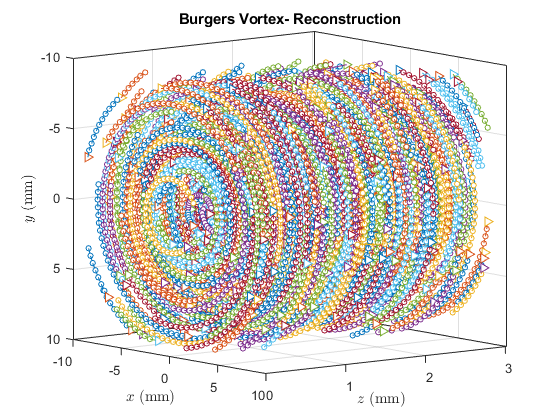

save([data_folder_path,'traj_GT.mat'],'traj_GT')

traj = struct with fields:
        xf: []
        yf: []
        zf: []
        uf: []
        vf: []
        wf: []
       axf: []
       ayf: []
       azf: []
         t: []
    trajid: []


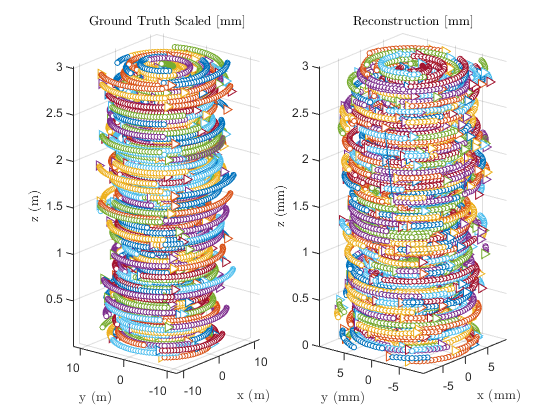

caz = -51.3402

cel = 8.8764

caz = -51.3402

cel = 8.8764

Undefined function or variable 'data_folder_path'.

% Save the Ground Truth Scaled Trajectory 
save([data_folder_path,'traj_GT_SCALED.mat'],'traj_GT_SCALED')
% Save the Reconstuction Trajectory
save([data_folder_path,'traj_RC.mat'],'traj_RC')
% Save the Dataset
save([data_folder_path,'test_data.mat'],'test_data')
% And save the entire workspace work space
save([data_folder_path,'Workspace.mat'])